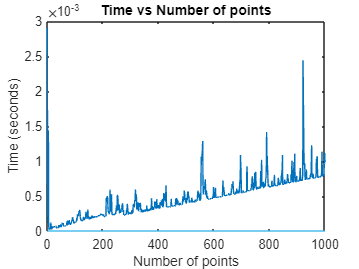

ns = linspace(10, 10000, 1000);
times = zeros(length(ns));
abs_errs = zeros(length(ns));

for i = 1:length(ns)
    tic;
    [monte_pi, abs_err, rel_err] = MontePi(ns(i));
    times(i) = toc;
    abs_errs(i) = abs_err;
end

plot(times);
title("Time vs Number of points");
xlabel("Number of points");
ylabel("Time (seconds)");

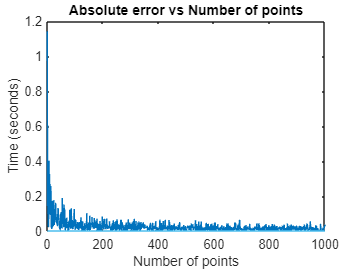


plot(abs_errs);
title("Absolute error vs Number of points");
xlabel("Number of points");
ylabel("Time (seconds)");

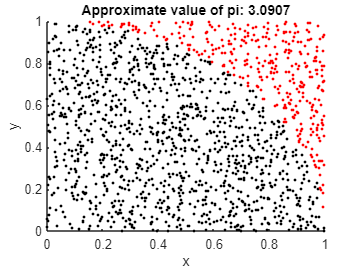


MontePi_plot(1500);

function [monte_pi, absolute_error, relative_error] = MontePi(n)
    %Number of points on or within circle
    num_inside_circle = 0;
    
    %Generate n points
    for i = 1:n
        %Generate random (x, y) coordinate
        coord = rand(2, 1);
        %Extract x and y components
        x = coord(1, 1);
        y = coord(2, 1);
        
        %Check whether or not the random point lies on or within the circle
        if x^2 + y^2 <= 1
            %If the point is on or within the circle, then increment the number which are by 1
            num_inside_circle = num_inside_circle + 1;
        end
    end
    
    % Calculate the approximation of pi using the Monte-Carlo method
    monte_quarter_pi = num_inside_circle / n;
    monte_pi = 4 * monte_quarter_pi;
    
    % Calculate the absolute error and relative error
    absolute_error = abs(monte_pi - pi);
    relative_error = absolute_error / pi;
end

function MontePi_plot(n)
    %Number of points on or within circle
    num_inside_circle = 0;

    %create figure for plotted data to live in
    figure;
       
    %Generate n points
    for i = 1:n
        hold on;
        %Generate random (x, y) coordinate
        coord = rand(1, 2);
        x = coord(1, 1);
        y = coord(1, 2);

        distance = sqrt(x^2 + y^2);

        %Check whether or not the random point lies on or within the circle
        if distance <= 1
            %If the point is on or within the circle, then increment the number which are by 1
            num_inside_circle = num_inside_circle + 1;
            plot(x, y, 'k.');
        else
            plot(x, y, 'r.');
        end
    end

    % Calculate the approximation of pi using the Monte-Carlo method
    monte_quarter_pi = num_inside_circle / n;
    monte_pi = 4 * monte_quarter_pi;

    title("Approximate value of pi: "+monte_pi);
    xlabel('x');
    ylabel('y');
end
